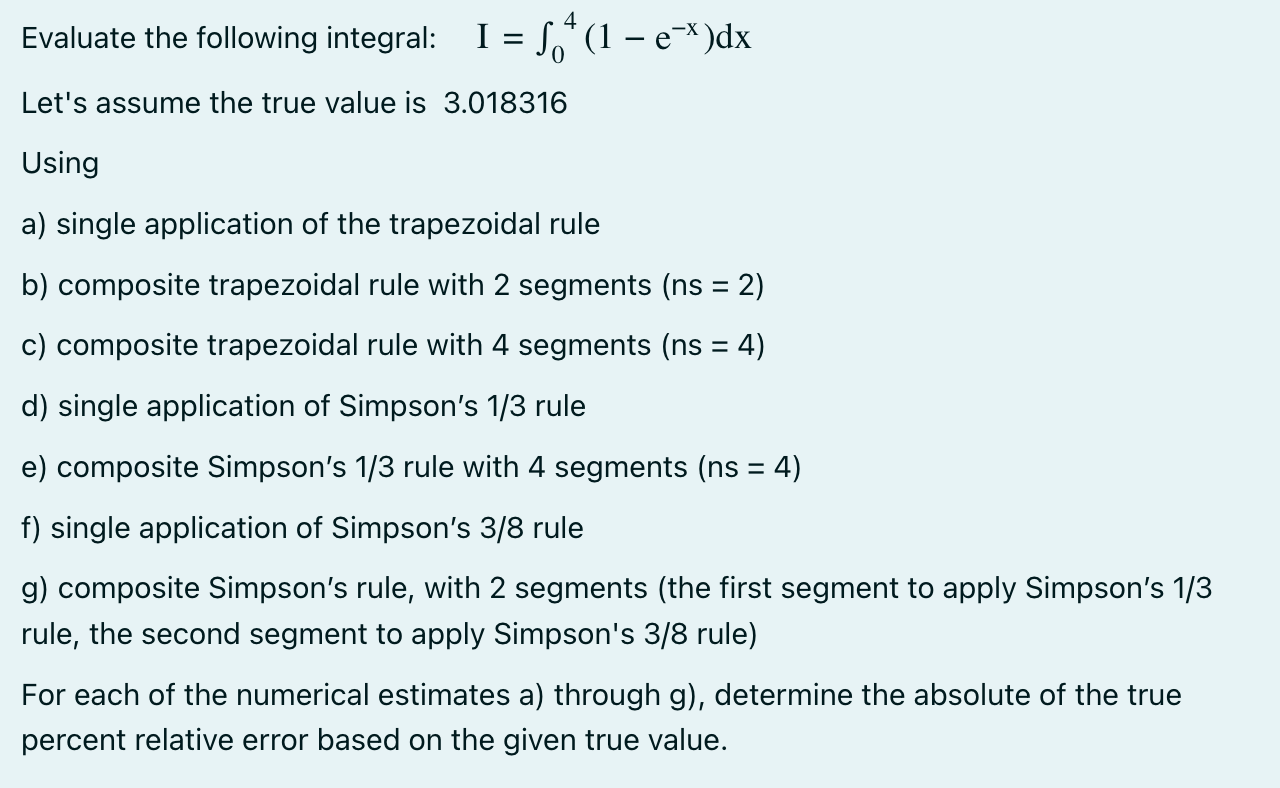

f = @(x) 1 - exp(-x);
a = 0;
b = 4;

I_true = 3.018316

I_true = 3.0183

(a)

I_trap1 = trap(f, a, b, 1)

I_trap1 = 1.9634

err = ((I_true - I_trap1) / I_true) * 100

err = 34.9515

(b)

I_trap2 = trap(f, a, b, 2)

I_trap2 = 2.7110

err = ((I_true - I_trap2) / I_true) * 100

err = 10.1812

©

I_trap4 = trap(f, a, b, 4)

I_trap4 = 2.9378

err = ((I_true - I_trap4) / I_true) * 100

err = 2.6662

(d)

ns = 1;
x = linspace(0, 4, 2 * ns + 1);
y = f(x);

h = (b-a)/2;
I_simp13_1 = (h/3) * ((y(1)) + 4*(y(2)) + y(3))

I_simp13_1 = 2.9602

err = ((I_true - I_simp13_1) / I_true) * 100

err = 1.9245

(e)

ns = 4;
x = linspace(0, 4, 2 * ns + 1);
y = f(x);

h = (b - a) / (ns * 2);
for i = 1:ns
    il = 2 * (i - 1) + 1;
    ir = 2 * i + 1;
    simp13_4(i) = (h/3) * ((y(il)) + 4*(y(il + 1)) + y(ir));
end
I_simp13_4 = sum(simp13_4)

I_simp13_4 = 3.0180

err = ((I_true - I_simp13_4) / I_true) * 100

err = 0.0110

(f)

ns = 1;
x = linspace(0, 4, 3 * ns + 1);
y = f(x);

h = (b-a)/3;
I_simp38_1 = (((3 * h) / 8) * (y(1) + (3 * y(2)) + (3 * y(3)) + y(4)))

I_simp38_1 = 2.9912

err = ((I_true - I_simp38_1) / I_true) * 100

err = 0.8977

(f)

ns = 2;
x = linspace(0, 2, 2 * ns + 1);
y = f(x);

h = (2-0)/2;
I_simp13 = (h/3) * ((y(1)) + 4*(y(2)) + y(3))

I_simp13 = 0.7353



ns = 4;
x = linspace(2, 4, 3 * ns + 1);
y = f(x);
h = (4-2)/3;
I_simp38 = (((3 * h) / 8) * (y(1) + (3 * y(2)) + (3 * y(3)) + y(4)))

I_simp38 = 1.7870


I_combined = I_simp13 + I_simp38

I_combined = 2.5223

err = abs((I_true - I_combined) / I_true) * 100

err = 16.4326